% read in table and format it to our liking.
clsTab=jellyfish.readClassification.import_classification_file_CJF('191121');

## separate the Phase 1 classification table

startDate=datetime('01/06/21 00:00','InputFormat',"dd/MM/yy HH:mm");
endDate=datetime('14/06/21 23:59','InputFormat',"dd/MM/yy HH:mm");

clsTabP1=jellyfish.readClassification.format_classification_table_CJF(clsTab,'start',startDate,'end',endDate);
%head(clsTab,5)
%clsTab=jellyfish.readClassification.simulationMask(clsTab,'TNG50');
% Classification info based on data downloaded on 14/7/21
% review and training set objecs classifications are removed. 
% The raw classification data is reformatted into a new table with columns contiaing the snapshot, id  Id for the object as well as the label (jelly or not):

## Separaete the phase 2 classification table

startDate=datetime('22/08/21 00:00','InputFormat',"dd/MM/yy HH:mm");
endDate=datetime('19/11/21 23:59','InputFormat',"dd/MM/yy HH:mm");

clsTabP2=jellyfish.readClassification.format_classification_table_CJF(clsTab,'start',startDate,'end',endDate);

## concatenate the twho phases

clsTab12=vertcat(clsTabP1,clsTabP2);

## Number of Inspections per Inspector 

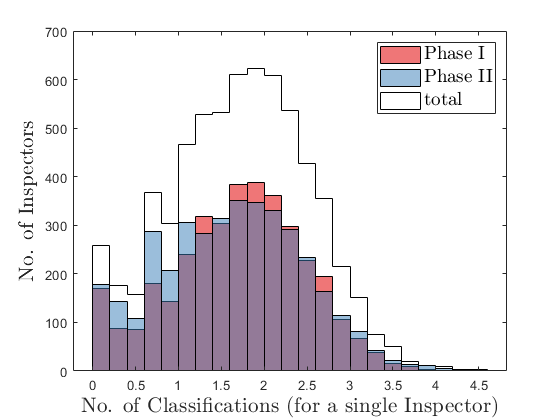

cmap=brewermap(5,'Set1');

% Get the number of classifications per inspector 
GC=groupcounts(clsTab12,'user_name');
GC1=groupcounts(clsTabP1,'user_name');
GC2=groupcounts(clsTabP2,'user_name');

figure

h(1)=histogram(log10(GC1.GroupCount),'DisplayStyle','bar','facecolor',cmap(1,:),...
    'Displayname','Phase I');
hold on
h(2)=histogram(log10(GC2.GroupCount),'DisplayStyle','bar','facecolor',cmap(2,:),...
    'Displayname','Phase II','facealpha',0.5);
h(3)=histogram(log10(GC.GroupCount),'edgecolor','k','DisplayStyle','stairs',...
    'DisplayNAme','total');
legend(h,'Interpreter','latex','location','northeast','fontsize',14)
xlabelmine('No. of Classifications (for a single Inspector)');
ylabelmine('No. of Inspectors');


fprintf('The average/median number of inspections in Phase I is: %f / %f',mean(GC1.GroupCount),median(GC1.GroupCount))

The average/median number of inspections in Phase I is: 211.061517 / 57.000000

fprintf('The average/median number of inspections in Phase II is: %f / %f',mean(GC2.GroupCount),median(GC2.GroupCount))

The average/median number of inspections in Phase II is: 268.279688 / 45.000000

fprintf('The average/median number of inspections overall is: %f / %f',mean(GC.GroupCount),median(GC2.GroupCount))

The average/median number of inspections overall is: 276.453957 / 45.000000

Word of warning  - the difference between mean and median results from some a few Inspectors with very high numbers  - but some of them are probably not individual Inspectors but generic names for  classifications from unsingned individuals. 


% who are the top Inspectors? 

%ntop=sum(GC.GroupCount>=1000);
fprintf('There are %i Inspectrors with more than 1000 inspections',sum(GC.GroupCount>=1000))

There are 325 Inspectrors with more than 1000 inspections

fprintf('There are %i Inspectrors with more than 5000 inspections',sum(GC.GroupCount>=5000))

There are 44 Inspectrors with more than 1000 inspections

fprintf('There are %i Inspectrors with more than 10000 inspections',sum(GC.GroupCount>=10000))

There are 17 Inspectrors with more than 10000 inspections


topT=GC(GC.GroupCount>=5000,:);
[~,ix]=sort(topT.GroupCount,'descend');
topT(ix,:)

ans = 44×2 table
       user_name       GroupCount
    _______________    __________

    "ssh"                36703   
    "IworkAtCostco"      36102   
    "enhudgens"          32723   
    "Jujujulz"           22278   
    "CFiligenzi"         21273   
    "Get2david"          20927   
    "Sunrise1324"        17923   
    "Prothon"            15448   
    "ElisabethB"         15439   
    "planetari7"         14379   
    "stephanie79"        14228   
    "tharshini"          13794   
    "Jan225"             11569   
    "Yukirvan"           11108   
    "lamperti"           11081   
    "myrikhan"           10848   


## Generate object tables for the two phases

% number of objects
%[idListP1, ~,~]=unique(clsTabP1.subject_ids);
[idListP1, ~,~]=unique(clsTabP1.tag);
ngalP1=length(idListP1);

fprintf('there are %i objects in Phase I\n',ngalP1)

[idListP2,~,~]=unique(clsTabP2.subject_ids);
ngalP2=length(idListP2);

[idListP2,~,~]=unique(clsTabP2.tag);
ngalP2=length(idListP2);
fprintf('there are %i objects in Phase II\n',ngalP2)


% create object table
objectTableP1=jellyfish.readClassification.build_object_table(clsTabP1);
objectTableP2=jellyfish.readClassification.build_object_table(clsTabP2);
objectTableP2=objectTableP2(5:end,:);  % remove first 4 objects with only 1 classification 
% table(idList,clsTab.simName(ia),clsTab.snap(ia),clsTab.subfind(ia),zeros(size(idList)),zeros(size(idList)),...
%     'variableNames',{'subject_ids','sim','snap','subfind','Ncls','Ycls'});

## add 20 excluded galaxis to phase I

for i=1:20
    if i<18
        ex20.sim(i,1)="TNG50";
    else
        ex20.sim(i,1)="TNG100";
    end
end
ex20.snap(1:5,1)="033";
ex20.snap(6:12,1)="040";
ex20.snap(13:15,1)=["050";"067";"072"];
ex20.snap(16:17,1)="078";
ex20.snap(18,1)="050";
ex20.snap(19:20,1)="059";
ex20.subfind=["00021560", "00050698", "00090630", "00127581", "00138654",...
"00000102", "00000126","00000158", "00036250", "00066110", "00112204", "00163074", "00079623", ...
 "00356638", "00091931", "00226474", "00451164", "00010011", "00301337", "00301338"]';

tg1(1:length(ex20.snap),1)="snp";
tg2(1:length(ex20.snap),1)="subid";
tg3(1:length(ex20.snap),1)="typ:";
tg4(1:length(ex20.snap),1)="rand";

ex20.tag=join([ex20.sim tg1 ex20.snap tg2 ex20.subfind tg3 tg4],'');

ex20Tab=table(zeros(20,1),ex20.sim,ex20.snap.double,ex20.subfind.double,ex20.tag,...
    zeros(20,1),zeros(20,1),zeros(20,1),tg4,...
    'variableNames',{'subject_ids','sim','snap','subfind','tag','clsNum','score','scoreTotal','type'});
objectTableP1=[objectTableP1 ; ex20Tab];

ngalP1=height(objectTableP1);
ngalP2=height(objectTableP2);
fprintf('there are %i objects in Phase I\n',ngalP1)
fprintf('there are %i objects in Phase II\n',ngalP2)


snapsP1=unique(objectTableP1.snap);
zredsP1=round(10.*illustris.utils.snap2redshift(snapsP1))./10;

snapsP2=unique(objectTableP2.snap);
zredsP2=round(10.*illustris.utils.snap2redshift(snapsP2))./10;

## build random orientation table

msk1=objectTableP1.type=="rand";
msk2=objectTableP2.type=="rand";
objectTable=[objectTableP1(msk1,:) ; objectTableP2(msk2,:)];
objectTablePref=[objectTableP1(~msk1,:) ; objectTableP2(~msk2,:)];

objectTableComp=objectTablePref(:,[1:5 7]);
objectTableComp.Properties.VariableNames(6)={'scorePref'};

for i=1:height(objectTableComp)
   ii=find(objectTable.tag.extractBefore("typ:")==objectTablePref.tag(i).extractBefore("typ:"));
   objectTableComp.scoreRand(i)=objectTable.score(ii);
end

## load object table

global DEFAULT_MATFILE_DIR
load([DEFAULT_MATFILE_DIR '/cosmic_jellyfish_objectTable.mat'],'objectTable','objectTablePref','objectTableComp');